## Teste de não linearidade

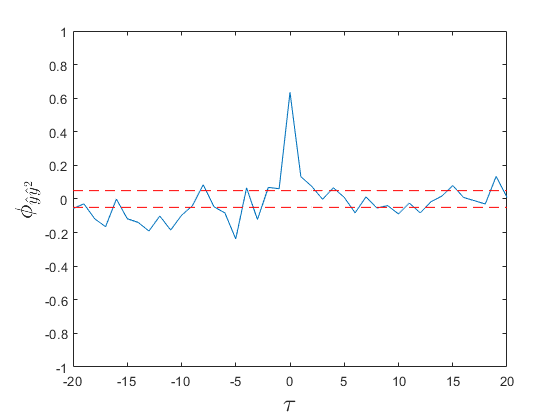

N = 30;
maxlag = 20;
entrada = rand([N 1])*2 - 0.8;
saida = zeros(N,1);
% ruido = normrnd(0,0.2,N,1);
% saida = xout(1:1000);
%%Não linear

for i = 2:N
    saida(i) = 0.5*saida(i-1)+0.2*entrada(i-1)+0.3*saida(i-1)*entrada(i-1)+0.6*entrada(i-1)^2+0.05*saida(i-1)^2;
end


dc_shift = mean(saida);
y_linha  = saida - dc_shift;
[Phi, xlims] = xcorr(y_linha, y_linha.^2, maxlag,"normalized");

size = length(Phi);
dim = [xlims(1) xlims(length(xlims))];
tol_sup = 0.05*ones(size,1);
tol_inf = -0.05*ones(size,1);

% tol = 1.96/sqrt(N);
% tol_sup = tol*ones(size,1);
% tol_inf = -tol*ones(size,1);

plot(xlims,Phi)
ylim([-1 1])
xlim(dim)
hold on;
plot(xlims, tol_sup,'r--')
plot(xlims, tol_inf,'r--')
hold off;
str = '$$\phi_{\hat{y}\hat{y}^2} $$';
ylabel(str,"FontSize",18,'Interpreter',"latex")
xlabel('$\tau$',"FontSize",18,"Interpreter","latex")

## Linear

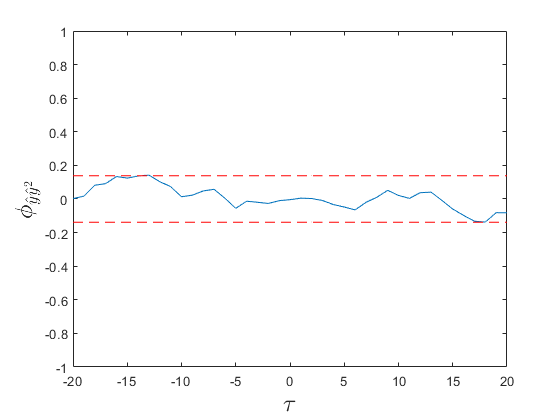

N = 200;
maxlag = 20;
entrada = rand([N 1])*2 - 0.8;
ruido = normrnd(0,0.05,N,1);

sys = tf(0.4,[1 -0.8],-1);

saida = lsim(sys, entrada);

saida = saida + ruido;

dc_shift = mean(saida);
y_linha = saida - dc_shift;
[Phi_lin,xlims] = xcorr(y_linha, y_linha.^2,maxlag,"normalized");

size = length(Phi_lin);
dim = [xlims(1) xlims(length(xlims))];

tol = 1.96/sqrt(N);
tol_sup = tol*ones(size,1);
tol_inf = -tol*ones(size,1);

figure
plot(xlims,Phi_lin)
ylim([-1 1])
xlim(dim)
hold on;
plot(xlims, tol_sup,'r--')
plot(xlims, tol_inf,'r--')
hold off;

str = '$$\phi_{\hat{y}\hat{y}^2} $$';
ylabel(str,"FontSize",18,'Interpreter',"latex")
xlabel('$\tau$',"FontSize",18,"Interpreter","latex")